# Ejemplo 

De la aproximción a la primera derivada de la función $f(x)$ en el punto $x=0.5$ usando diferencias finitas centradas de orden $O(h^2)$, encontrar el valor $h_{opt$ para el cual los errores se minimizan.


$$f(x)=-0.1x^4-0.15x^3-0.5x^2-0.25x+1.2$$


y donde 


$$h_{opt}=\sqrt[3]{\frac{3\varepsilon}{M}}$$


Graficar el tamaño del paso paso $h$ contra el error total para cada uno de los pasos.

% Función a estudiar en el punto x=0.5
f = @(x) -0.1*x.^4 - 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.2;
df = @(x) -0.4*x.^3 - 0.45*x.^2 - x - 0.25;
ddf = @(x) -1.2*x.^2 - 0.9*x - 1;
dddf = @(x) -2.4*x - 0.9;
% valro verdadera de la derivada en x = 0.5
df_verd = round(df(0.5),4);

% Paso inicial
h = 1;
x = 0.5;

% Arreglos iniciales
h_val = [];
der_aprox_v = [];
errores = [];

% Ciclo para calcular el erro dividiendo el paso en cada vuelta sobre 10
for i = 1:15
    % Aproximación por diferencias finitas centradas de O(h^2)
    der_aprox = (f(x + h) - f(x - h)) / (2 * h);
    
    % Vectores de valores
    h_val = [h_val, h]; % tamaño de paso
    der_aprox_v = [der_aprox_v, der_aprox]; %derivada aproximada f'-tilde
    errores = [errores, abs(df_verd - der_aprox)]; % error
    
    % Tabla 
    fprintf('h = %e, df-aprox = %.10f, Error = %e\n', h, der_aprox, abs(true_value - der_aprox));
    
    % Se reduce el paso 1/10 para el siguiente ciclo
    h = h / 10;
end

h = 1.000000e+00, df-aprox = -1.2625000000, Error = 3.500000e-01
h = 1.000000e-01, df-aprox = -0.9160000000, Error = 3.500000e-03
h = 1.000000e-02, df-aprox = -0.9125350000, Error = 3.500000e-05
h = 1.000000e-03, df-aprox = -0.9125003500, Error = 3.500000e-07
h = 1.000000e-04, df-aprox = -0.9125000035, Error = 3.499850e-09
h = 1.000000e-05, df-aprox = -0.9125000000, Error = 3.317835e-11
h = 1.000000e-06, df-aprox = -0.9125000000, Error = 5.422773e-12
h = 1.000000e-07, df-aprox = -0.9124999995, Error = 5.496888e-10
h = 1.000000e-08, df-aprox = -0.9125000033, Error = 3.336092e-09
h = 1.000000e-09, df-aprox = -0.9125000200, Error = 1.998944e-08
h = 1.000000e-10, df-aprox = -0.9125000755, Error = 7.550059e-08
h = 1.000000e-11, df-aprox = -0.9125034062, Error = 3.406170e-06
h = 1.000000e-12, df-aprox = -0.9124923039, Error = 7.696061e-06
h = 1.000000e-13, df-aprox = -0.9126033262, Error = 1.033262e-04
h = 1.000000e-14, df-aprox = -0.9103828802, Error = 2.117120e-03


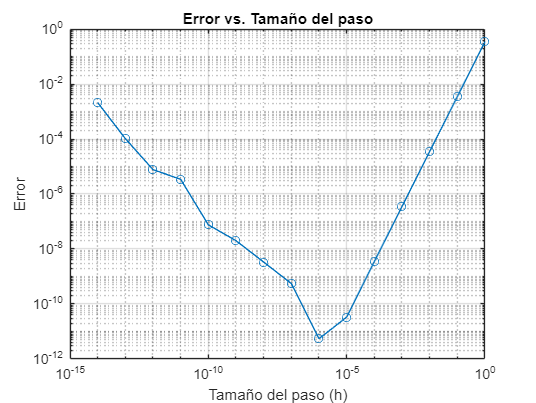


% Grafica log-log
loglog(h_val, errores, '-o');
xlabel('Tamaño del paso (h)');
ylabel('Error');
title('Error vs. Tamaño del paso');
grid on;


%Cálculo del paso óptimo
epsilon_m=eps; %obtenemos el epsilon de la maquina

fprintf('h_optimo es %.10e',(3*abs(epsilon_m)*x/abs(dddf(x)))^(1/3))

h_optimo es 5.4129921416e-06